clear;
clc;
format long

knn = load('knn.mat').knn;
rf = load('rf.mat').rf;
nb = load('nb.mat').nb;
total = load('totalFeatures.mat').total;
labels = load('labels.mat').labels;
Xtrain = total(1:299,:);
Xtest = total(300:426,:);
Ytrain = labels(1:299);
Ytest = labels(300:426);
MRMR = load('MRMR.mat').MRMR;
idxMRMR = MRMR(1,:);
scores = MRMR(2,:);

mdl = fitcknn(Xtrain(:,idxMRMR(1:12)), Ytrain, 'NumNeighbors',3, "Standardize",1);
preds = predict(mdl, Xtest(:,idxMRMR(1:12)));
disp(mean(preds==Ytest))

   0.724409448818898



mdl = fitcnb(Xtrain(:,idxMRMR(1:12)), Ytrain);
preds = predict(mdl, Xtest(:,idxMRMR(1:12)));
disp(mean(preds==Ytest))

   0.740157480314961



mdl = fitensemble(Xtrain(:,idxMRMR(1:9)),Ytrain, 'Bag', 90, 'Tree', 'Type', 'classification');
preds = predict(mdl, Xtest(:,idxMRMR(1:9)));
disp(mean(preds==Ytest))

   0.740157480314961



Xtrain = load('Xtrain.mat').Xtrain;
Ytrain = load('Ytrain.mat').Ytrain;
Xtest = load('Xtest.mat').Xtest;
Ytest = load('Ytest.mat').Ytest;
MRMR = load('MRMR.mat').MRMR;
idxMRMR = MRMR(1,:);
scores = MRMR(2,:);

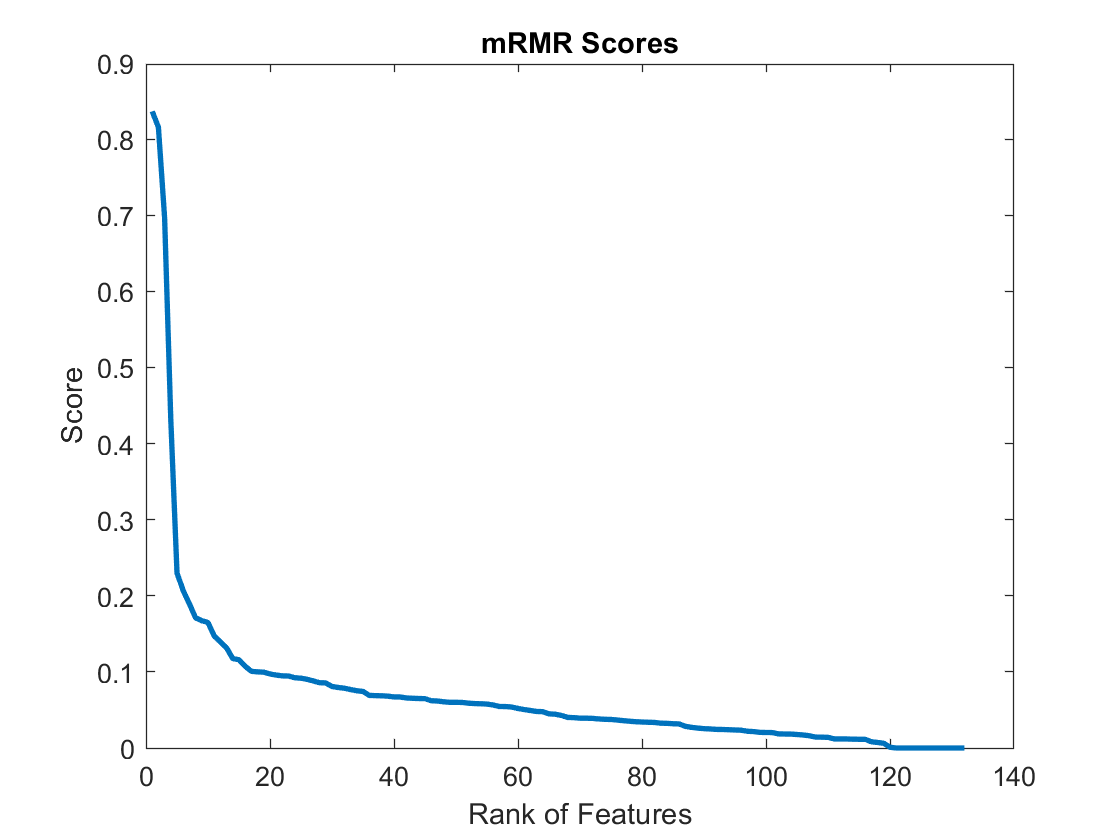

figure;
plot([1:length(idxMRMR)], scores(idxMRMR),'LineWidth',2);
title('mRMR Scores');
xlabel('Rank of Features');
ylabel('Score');

[predk,scorek,~] = predict(knn, Xtest(:,idxMRMR(1:12)));
[predr,scorer] = predict(rf, Xtest(:,idxMRMR(1:9)));
[predn,scoren] = predict(nb, Xtest(:,idxMRMR(1:12)));

[X_knn_n,Y_knn_n,T,AUCknn_n] = perfcurve(Ytest,scorek(:,1),'Necrosis');
[X_knn_s,Y_knn_s,T,AUCknn_s] = perfcurve(Ytest,scorek(:,2),'Stroma');
[X_knn_t,Y_knn_t,T,AUCknn_t] = perfcurve(Ytest,scorek(:,3),'Tumor');
[X_rf_n,Y_rf_n,T,AUCrf_n] = perfcurve(Ytest,scorer(:,1),'Necrosis');
[X_rf_s,Y_rf_s,T,AUCrf_s] = perfcurve(Ytest,scorer(:,2),'Stroma');
[X_rf_t,Y_rf_t,T,AUCrf_t] = perfcurve(Ytest,scorer(:,3),'Tumor');
[X_nb_n,Y_nb_n,T,AUCnb_n] = perfcurve(Ytest,scoren(:,1),'Necrosis');
[X_nb_s,Y_nb_s,T,AUCnb_s] = perfcurve(Ytest,scoren(:,2),'Stroma');
[X_nb_t,Y_nb_t,T,AUCnb_t] = perfcurve(Ytest,scoren(:,3),'Tumor');

disp(mean(predr==Ytest))

    0.9921



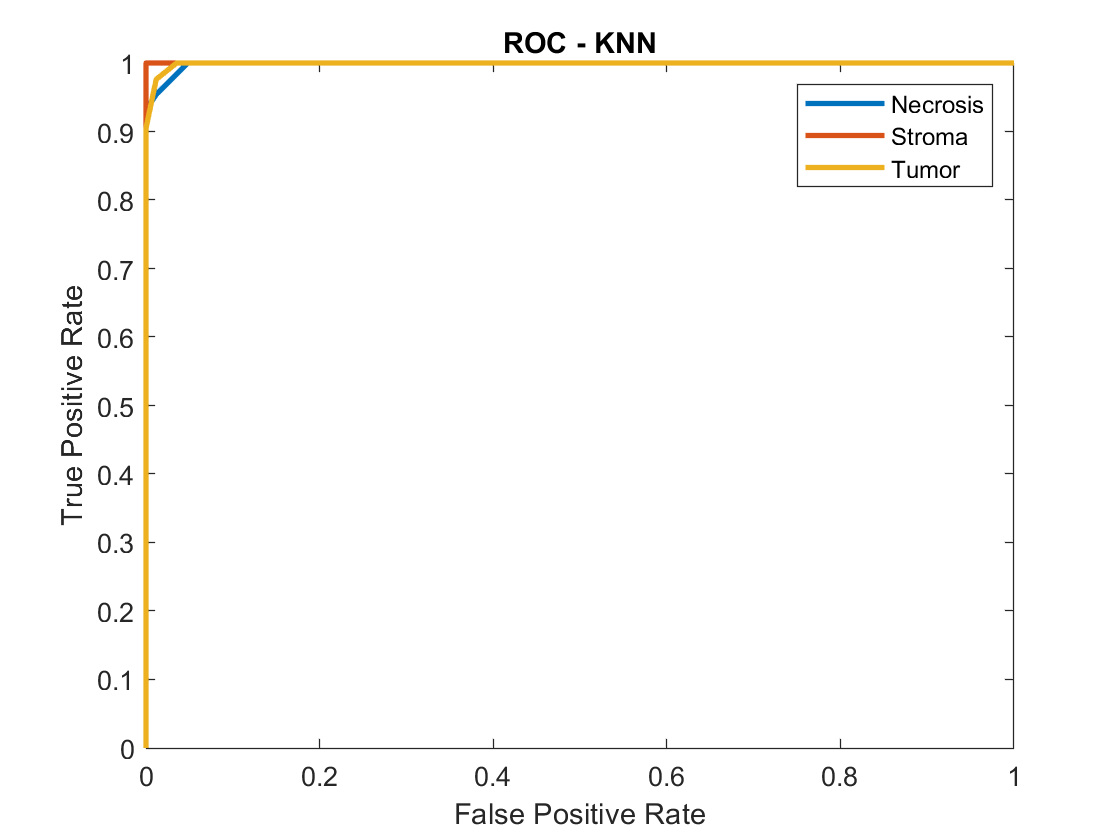

figure;
plot(X_knn_n, Y_knn_n,'Linewidth',2)
hold on
plot(X_knn_s, Y_knn_s,'Linewidth',2)
plot(X_knn_t, Y_knn_t,'Linewidth',2)
title('ROC - KNN');
xlabel('False Positive Rate')
ylabel('True Positive Rate')
legend('Necrosis','Stroma','Tumor');

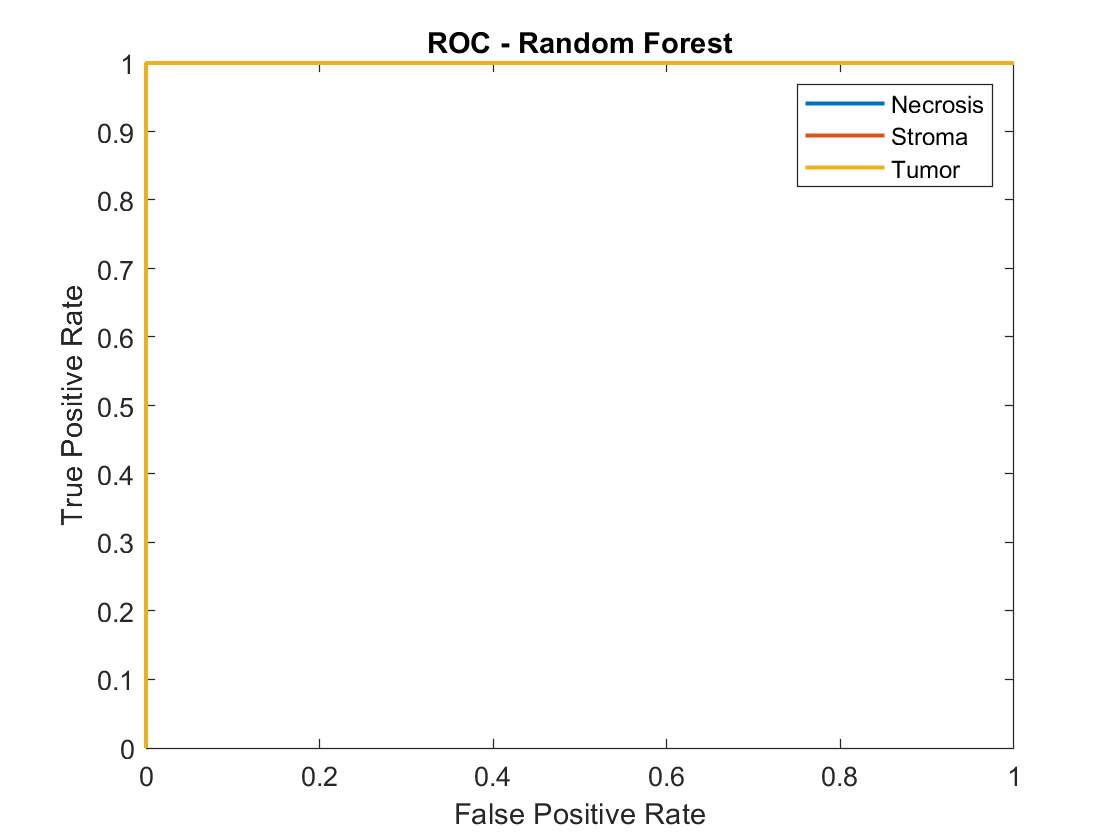

figure;
plot(X_rf_n, Y_rf_n,'Linewidth',1.5)
hold on
plot(X_rf_s, Y_rf_s,'Linewidth',1.5)
plot(X_rf_t, Y_rf_t,'Linewidth',1.5)
title('ROC - Random Forest');
xlabel('False Positive Rate')
ylabel('True Positive Rate')
legend('Necrosis','Stroma','Tumor');

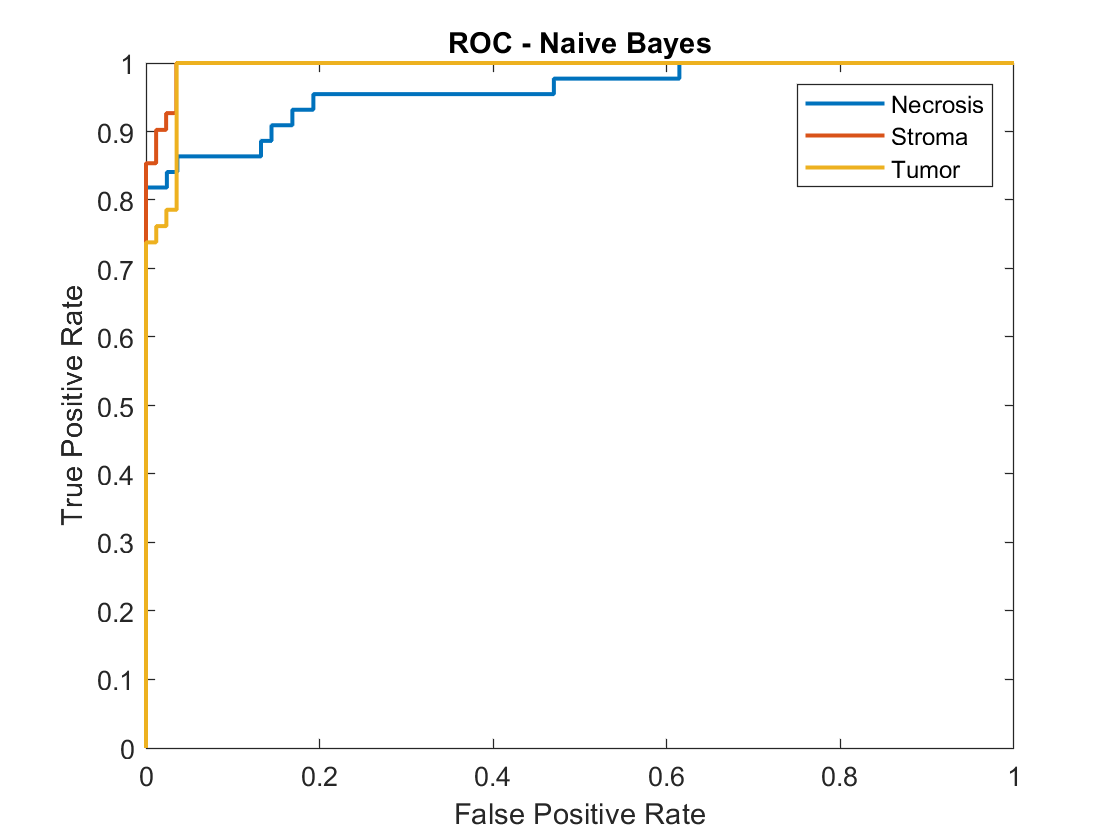

figure;
plot(X_nb_n, Y_nb_n,'Linewidth',1.5)
hold on
plot(X_nb_s, Y_nb_s,'Linewidth',1.5)
plot(X_nb_t, Y_nb_t,'Linewidth',1.5)
title('ROC - Naive Bayes');
xlabel('False Positive Rate')
ylabel('True Positive Rate')
legend('Necrosis','Stroma','Tumor');

tpNk = sum(ismember(Ytest,'Necrosis') & ismember(predk,'Necrosis'));
tpSk = sum(ismember(Ytest,'Stroma') & ismember(predk,'Stroma'));
tpTk = sum(ismember(Ytest,'Tumor') & ismember(predk,'Tumor'));
fpNk = sum(ismember(predk,'Necrosis')) - tpNk;
fpSk = sum(ismember(predk,'Stroma')) - tpSk;
fpTk = sum(ismember(predk,'Tumor')) - tpTk;
fnNk = sum(ismember(Ytest, 'Necrosis')) - tpNk;
fnSk = sum(ismember(Ytest, 'Stroma')) - tpSk;
fnTk = sum(ismember(Ytest, 'Tumor')) - tpTk;
f1Nk = tpNk/(tpNk + (fpNk+fnNk)/2);
f1Sk = tpSk/(tpSk + (fpSk+fnSk)/2);
f1Tk = tpTk/(tpTk + (fpTk+fnTk)/2);

tpNr = sum(ismember(Ytest,'Necrosis') & ismember(predr,'Necrosis'));
tpSr = sum(ismember(Ytest,'Stroma') & ismember(predr,'Stroma'));
tpTr = sum(ismember(Ytest,'Tumor') & ismember(predr,'Tumor'));
fpNr = sum(ismember(predr,'Necrosis')) - tpNr;
fpSr = sum(ismember(predr,'Stroma')) - tpSr;
fpTr = sum(ismember(predr,'Tumor')) - tpTr;
fnNr = sum(ismember(Ytest, 'Necrosis')) - tpNr;
fnSr = sum(ismember(Ytest, 'Stroma')) - tpSr;
fnTr = sum(ismember(Ytest, 'Tumor')) - tpTr;
f1Nr = tpNr/(tpNr + (fpNr+fnNr)/2);
f1Sr = tpSr/(tpSr + (fpSr+fnSr)/2);
f1Tr = tpTr/(tpTr + (fpTr+fnTr)/2);

tpNn = sum(ismember(Ytest,'Necrosis') & ismember(predn,'Necrosis'));
tpSn = sum(ismember(Ytest,'Stroma') & ismember(predn,'Stroma'));
tpTn = sum(ismember(Ytest,'Tumor') & ismember(predn,'Tumor'));
fpNn = sum(ismember(predn,'Necrosis')) - tpNn;
fpSn = sum(ismember(predn,'Stroma')) - tpSn;
fpTn = sum(ismember(predn,'Tumor')) - tpTn;
fnNn = sum(ismember(Ytest, 'Necrosis')) - tpNn;
fnSn = sum(ismember(Ytest, 'Stroma')) - tpSn;
fnTn = sum(ismember(Ytest, 'Tumor')) - tpTn;
f1Nn = tpNn/(tpNn + (fpNn+fnNn)/2);
f1Sn = tpSn/(tpSn + (fpSn+fnSn)/2);
f1Tn = tpTn/(tpTn + (fpTn+fnTn)/2);